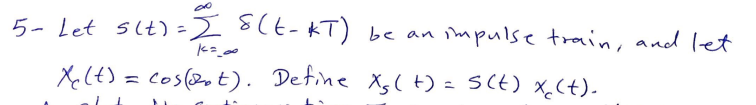

w = 1;
T = 2*pi/(3*w)

T = 2.0944

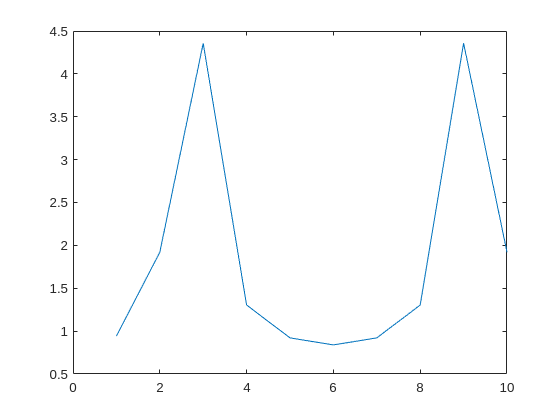


n = -10:T:10;
x_c = cos(w*n);

dtft = fft(x_c);
plot(abs(fftshift(dtft)))

w = 1;
T = 4*pi/(3*w)

T = 4.1888

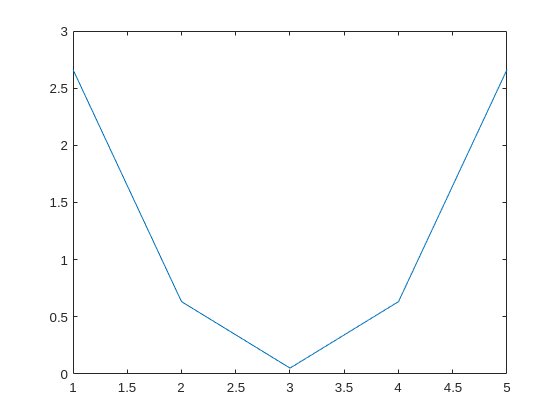


n = -10:T:10;
x_c = cos(w*n);

dtft = fft(x_c);
plot(abs(fftshift(dtft)))

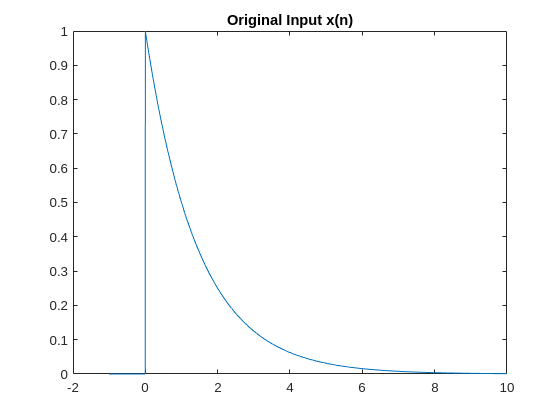

T = 0.0001;
n = -1:T:10;
x = (0.5.^n).*heaviside(n);
m = 3;
l = 2;

plot(n, x)
title("Original Input x(n)")

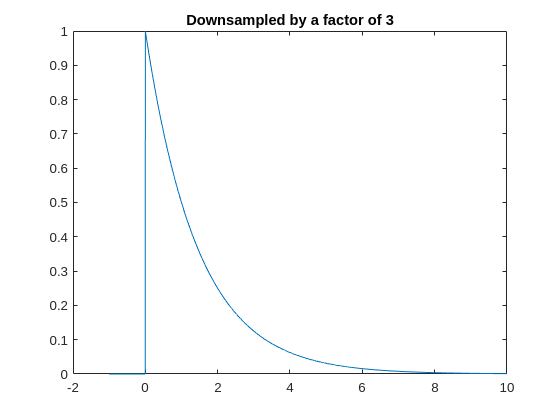


x_d = downsample(x,m);
n_d = -1:T*m:10;

plot(n_d,x_d)
title("Downsampled by a factor of " + string(m))

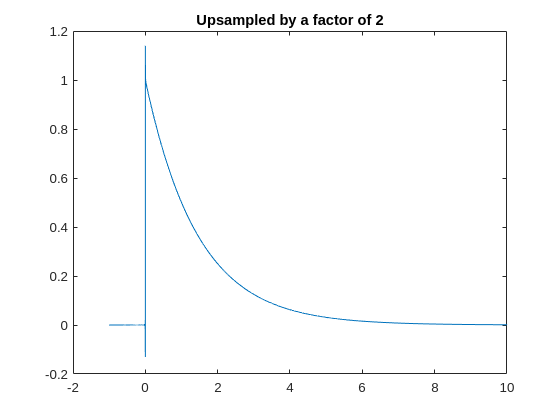


x_u = DSP_funcs.resampleSINC(x_d, l);
n_u = -1:T*m/l:10;
plot(n_u,x_u(1:length(n_u)))
title("Upsampled by a factor of " + string(l))